## Example with triangles

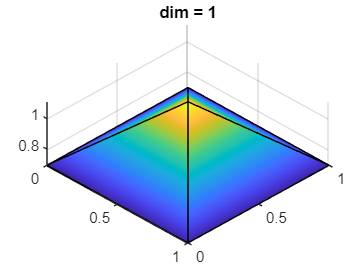

clear;

x1       = linspace(0,1,2);
x2       = linspace(0,1,2);
[xv,yv]  = meshgrid(x1,x2);
[F,V]    = mesh2tri(xv,yv,zeros(size(xv)),'x');
m.coord  = V(:,1:2);
m.connec = F;
mesh     = Mesh(m);

gPar.type          = 'Circle';
gPar.radius        = 0.25;
gPar.xCoorCenter   = 0.5;
gPar.yCoorCenter   = 0.5;
g                  = GeometricalFunction(gPar);
phiFun             = g.computeLevelSetFunction(mesh);
lsCircle           = phiFun.fValues;
lsCircleInclusion  = -lsCircle;
sUm.backgroundMesh = mesh;
sUm.boundaryMesh   = mesh.createBoundaryMesh;
uMesh              = UnfittedMesh(sUm);
uMesh.compute(lsCircleInclusion);


sAF.fHandle = @(x) 1-(x(1,:,:)-0.5).^2-(x(2,:,:)-0.5).^2;
sAF.ndimf   = 1;
sAF.mesh    = mesh;
aFun       = AnalyticalFunction(sAF);
aFun.plot();
view(45,60);

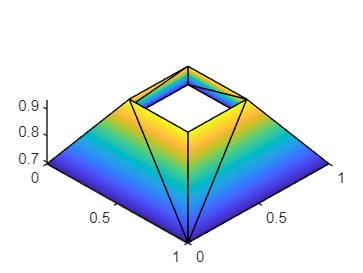


uMeshFun = uMesh.obtainFunctionAtUnfittedMesh(aFun);
uMeshFun.plot();
view(45,60);

## Example with lines

clear;

x1       = linspace(0,1,5);
x2       = linspace(0,1,5);
[xv,yv]  = meshgrid(x1,x2);
[F,V]    = mesh2tri(xv,yv,zeros(size(xv)),'x');
m.coord  = V(:,1:2);
m.connec = F;
mesh     = Mesh(m);


gPar.type          = 'VerticalFiber';
gPar.width         = 0.25;
gPar.xCoorCenter   = 0.5;
g                  = GeometricalFunction(gPar);
phiFun             = g.computeLevelSetFunction(mesh);
lsCircle           = phiFun.fValues;
lsCircleInclusion  = -lsCircle;
sUm.backgroundMesh = mesh;
sUm.boundaryMesh   = mesh.createBoundaryMesh;
uMesh              = UnfittedMesh(sUm);
uMesh.compute(lsCircleInclusion);
uMeshLine          = uMesh.unfittedBoundaryMesh.meshes{3};


sAF.fHandle = @(x) 1-(x(1,:,:)-0.5).^2;
sAF.ndimf   = 1;
sAF.mesh    = uMeshLine.backgroundMesh;
aFun       = AnalyticalFunction(sAF);

uMeshFun = uMeshLine.obtainFunctionAtUnfittedMesh(aFun);

## Example with quads

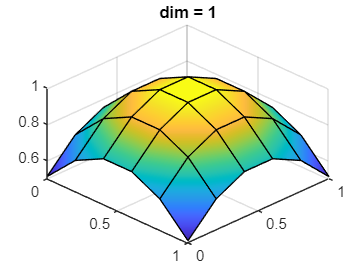

clear;

mesh = UnitQuadMesh(5,5);

gPar.type          = 'Circle';
gPar.radius        = 0.25;
gPar.xCoorCenter   = 0.5;
gPar.yCoorCenter   = 0.5;
g                  = GeometricalFunction(gPar);
phiFun             = g.computeLevelSetFunction(mesh);
lsCircle           = phiFun.fValues;
lsCircleInclusion  = -lsCircle;
sUm.backgroundMesh = mesh;
sUm.boundaryMesh   = mesh.createBoundaryMesh;
uMesh              = UnfittedMesh(sUm);
uMesh.compute(lsCircleInclusion);


sAF.fHandle = @(x) 1-(x(1,:,:)-0.5).^2-(x(2,:,:)-0.5).^2;
sAF.ndimf   = 1;
sAF.mesh    = mesh;
aFun       = AnalyticalFunction(sAF);
aFun.plot();
view(45,45);

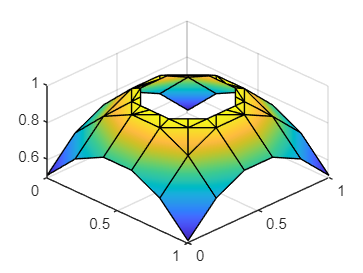


uMeshFun = uMesh.obtainFunctionAtUnfittedMesh(aFun);
uMeshFun.plot();
view(45,45);

## Example with tetrahedra

clear;

Mesh:

X    = [0 ,0, 0;...
        1, 0, 0;...
        0, 1, 0;...
        1, 1, 0;...
        0, 0, 1;...
        1, 0, 1;...
        0, 1, 1;...
        1, 1, 1;];
DT = delaunayTriangulation(X);
s.coord = X;
s.connec = DT.ConnectivityList;
mesh = Mesh(s);

ls = [-1;-1;-1;-1;1;1;1;1];

sUm.backgroundMesh = mesh;
sUm.boundaryMesh   = mesh.createBoundaryMesh;
uMesh              = UnfittedMesh(sUm);
uMesh.compute(ls);


sAF.fHandle = @(x) 1-(x(1,:,:)-0.5).^2-(x(2,:,:)-0.5).^2-(x(3,:,:)-0.5).^2;
sAF.ndimf   = 1;
sAF.mesh    = mesh;
aFun       = AnalyticalFunction(sAF);

uMeshFun = uMesh.obtainFunctionAtUnfittedMesh(aFun);

## Example with hexahedra

clear;

Mesh:

s.coord = [0 ,0, 0;...
        1, 0, 0;...
        0, 1, 0;...
        1, 1, 0;...
        0, 0, 1;...
        1, 0, 1;...
        0, 1, 1;...
        1, 1, 1;];
s.connec = [1,2,4,3,5,6,8,7];
mesh = Mesh(s);

ls = [-1;-1;-1;-1;1;1;1;1];

sUm.backgroundMesh = mesh;
sUm.boundaryMesh   = mesh.createBoundaryMesh;
uMesh              = UnfittedMesh(sUm);
uMesh.compute(ls);


sAF.fHandle = @(x) 1-(x(1,:,:)-0.5).^2-(x(2,:,:)-0.5).^2-(x(3,:,:)-0.5).^2;
sAF.ndimf   = 1;
sAF.mesh    = mesh;
aFun       = AnalyticalFunction(sAF);

uMeshFun = uMesh.obtainFunctionAtUnfittedMesh(aFun);